% -----------------------------------------
% Assignment for ODE with b.c.
% LiXin
% 2022/4/14
% -----------------------------------------

Problem 1

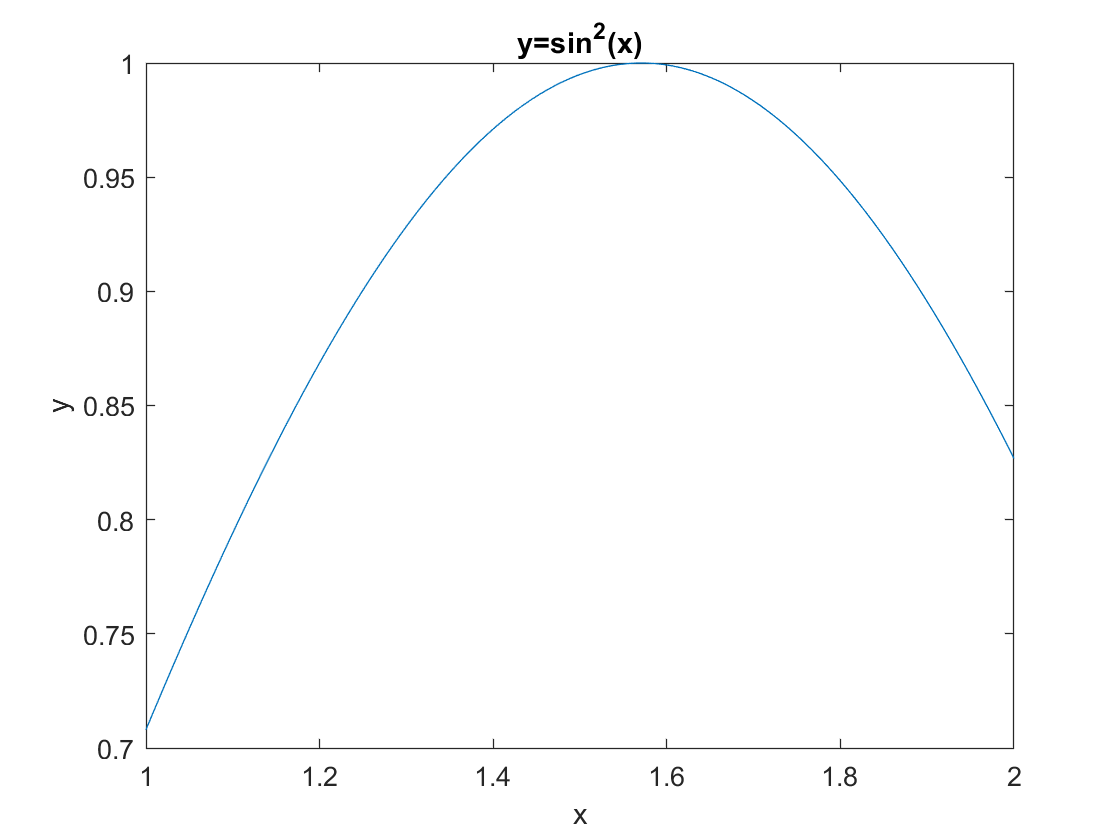

clear; close; clc;
xlow=1; xhigh=2;
x=linspace(xlow,xhigh,100);
y1=sin(x).^2;
solinit=bvpinit(x, [1 0]);
y2=bvp4c(@p1,@p1c,solinit);
plot(x,y1), title('y=sin^2(x)'), xlabel('x'), ylabel('y');

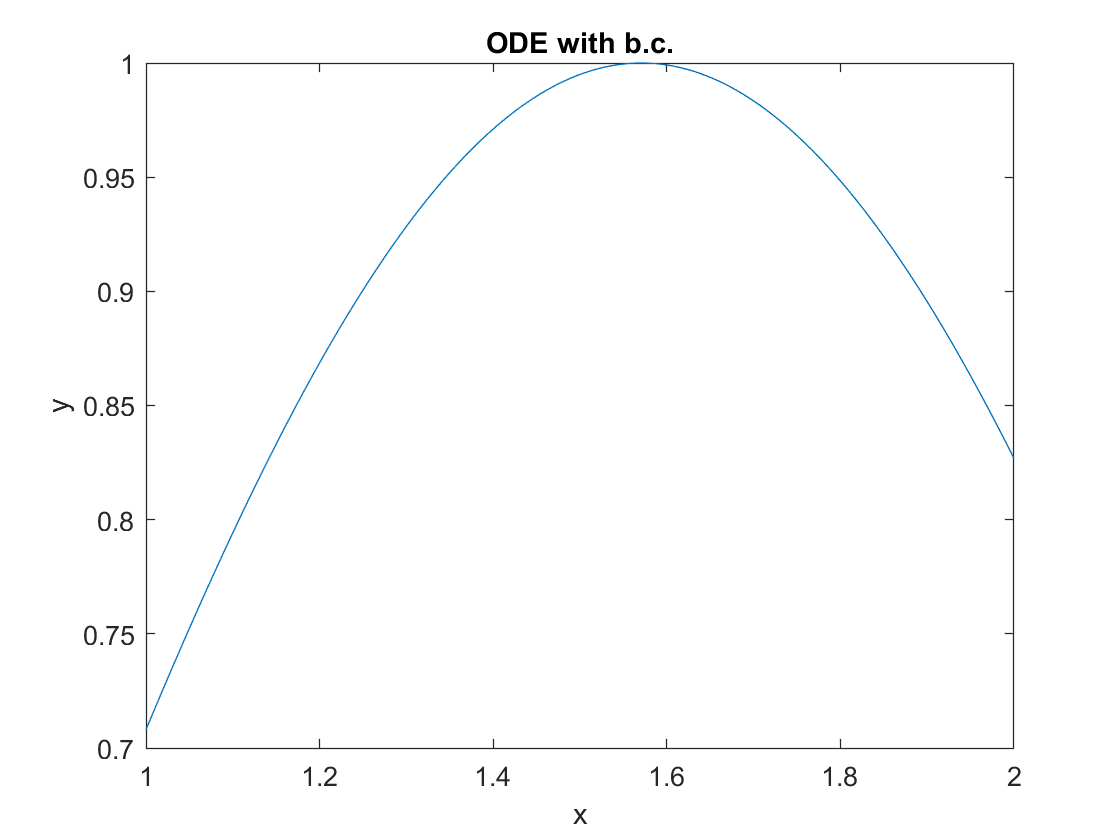

plot(y2.x,y2.y(1,:)), title('ODE with b.c.'), xlabel('x'), ylabel('y');

Problem 2

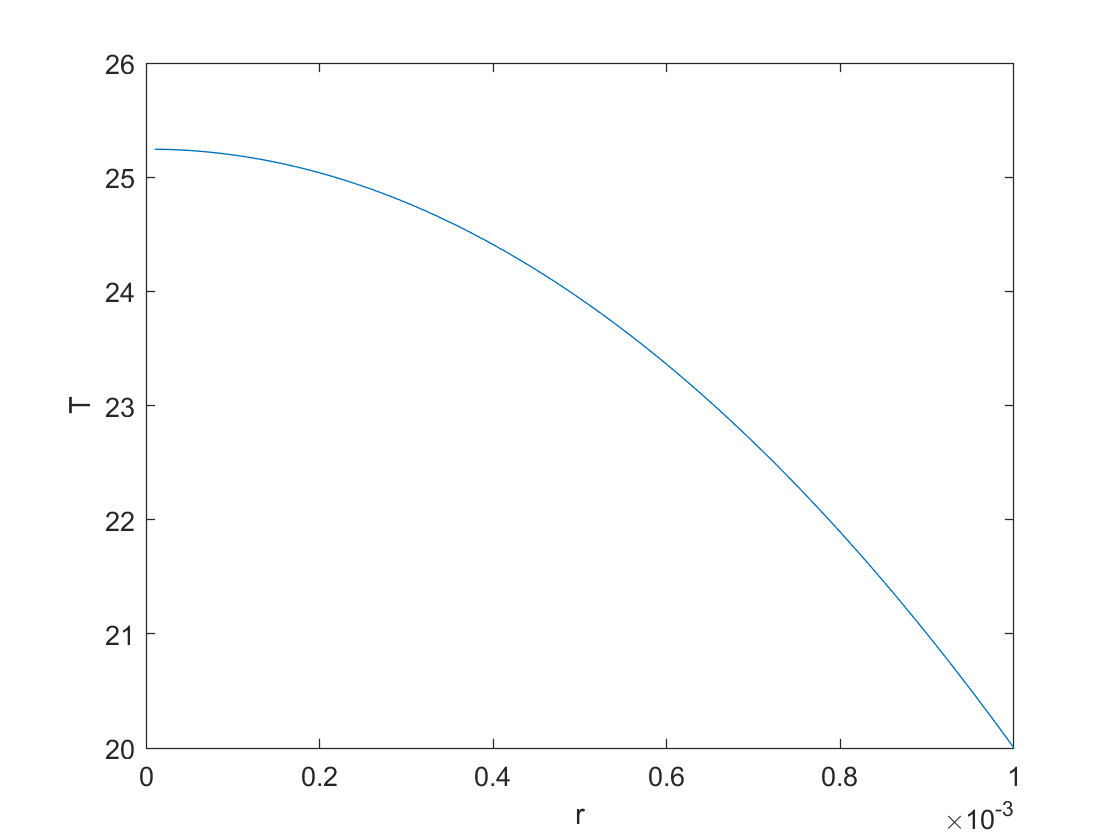

clear; close; clc;
xlow=0.00001; xhigh=0.001;
x=linspace(xlow,xhigh,100);
solinit=bvpinit(x,[1 0]);
y=bvp4c(@p2,@p2c,solinit);
plot(y.x,y.y(1,:)), ylabel('T'), xlabel('r')

From the figure, the peak temperature is approximately 25.2C

Problem 3

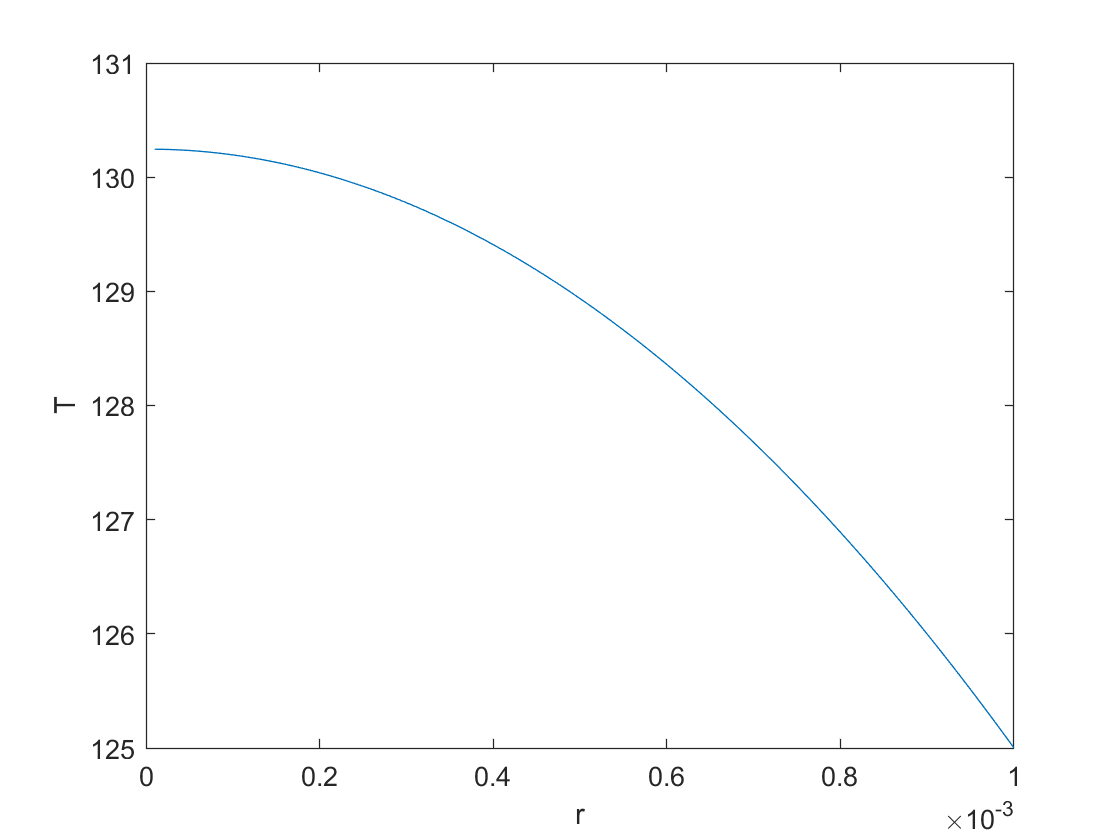

clear; close; clc;
xlow=0.00001;xhigh=0.001;
x=linspace(xlow,xhigh,100);
solinit=bvpinit(x,[1 0]);
y=bvp4c(@p2,@p3c,solinit);
plot(y.x,y.y(1,:)), ylabel('T'), xlabel('r')

From the figure, the peak temperature is approximately 130.2C

function res=p1(t, y)
res=[y(2) 2-4*y(1)^2/(sin(t)^2)];
end

function res=p1c(ya, yb)
res=[ya(2)-2*sin(1)*cos(1) yb(1)-sin(2)^2];
end

function res=p2(t, y)
Q=2.1*10^6;k=0.1;
res=[y(2) -Q/k-1/t*y(2)];
end

function res=p2c(ya, yb)
res=[ya(2) yb(1)-20];
end

function res=p3c(ya, yb)
h=10;Te=20;Q=2.1*10^6;R=0.001;
res=[ya(2) yb(1)-1/2/h*Q*R-Te];
end